%Scripts for randlanet model training, tested in MATLAB R2023b.
%Remember to add scripts folder in Path!!
%Lidar toolbox and Deep learning toolbox has to be installed!!
%original: https://se.mathworks.com/help/lidar/ug/aerial-lidar-semantic-segmentation-using-randlanet-deep-learning.html

dataFolder = fullfile(pwd,'/dataset/'); %dataset folder
testDataFolder = fullfile(dataFolder,"test"); %test data folder
trainDataFolder = fullfile(dataFolder,"train"); %train data folder
modelFolder = fullfile(pwd,"randlanet_models"); %model data folder
outputFolder = fullfile(dataFolder,"PreprocessedTrainData"); %preproccessed train data folder

%Traindata preprocess to speed up model training.

writeFiles = true; %set false if dont want preprocess again.
removeClasses = [0,4] %which classes to remove from training data as a number. e.g. 0 = other tree, 4 = ground.

removeClasses =      0     4


classNames = ["Stem";"Branch";"Leaf"] %names of left classes

classNames = 3×1 string array
    "Stem"
    "Branch"
    "Leaf"


numClasses = numel(classNames); %get number of classes 
gridSize = 0.01; %Point cloud density to downsample.

fds = fileDatastore(trainDataFolder,"ReadFcn",@lasFileReader);
ldsTransformed = transform(fds,@(x) helperTransformTrainData(x,gridSize,removeClasses));
if writeFiles
    writeall(ldsTransformed,outputFolder,WriteFcn = @helperDatastoreWriteFcn,FolderLayout = "flatten");
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 14 workersProcessing done for file: 407A1.las

%Set training

pcCropTrainPath = fullfile(outputFolder,"PointCloud"); %preprocessed point cloud folder
labelCropTrainPath = fullfile(outputFolder,"Labels");%preproccessed label folder
weights = helperComputeClassWeights(fds,numClasses);
ldsTrain = fileDatastore(pcCropTrainPath,"ReadFcn",@(x) pcread(x));
labelIDs = 1 : numClasses; %set label ID:s numbers. 
pxdsTrain = pixelLabelDatastore(labelCropTrainPath,classNames,labelIDs);
preprocessedTrainingData = transform(ldsTrain,pxdsTrain,@(pt,lb) helperPreprocessTrainData(pt,lb,classNames));
randlanetFolder = fullfile(modelFolder,'untrainedRandLANet.mat');
net = helperLoadRandLANet(numClasses,randlanetFolder); %load untrained randlanet network.

%Set training parameters 

learningRate = 0.005; %how big steps model weights take. Too High: model learns fast but is unprecise. Too Low: model does not learn.
numEpochs = 1; %how many training cycles trought whole training dataset.
miniBatchSize = 4; %hom many point clouds same time to training. Higher value needs powerfull computer but training faster.
learnRateDropFactor = 0.9886; %how much learningRate decreases when after epocs. e.g. 0.005*0.9886...
executionEnvironment = "auto";
dataFormat = cell(1,26);
dataFormat(:) = {'SSCB'}; 

options = trainingOptions("adam", ...
    InitialLearnRate = learningRate, ...
    MaxEpochs = numEpochs, ...
    MiniBatchSize = miniBatchSize, ...
    LearnRateSchedule = "piecewise", ...
    LearnRateDropPeriod = 1,...
    LearnRateDropFactor = learnRateDropFactor, ...
    Plots = "training-progress", ...
    ExecutionEnvironment = executionEnvironment, ...
    ResetInputNormalization = false, ...
    CheckpointFrequencyUnit = "epoch", ...
    CheckpointFrequency = 10, ... 
    CheckpointPath = tempdir, ...
    InputDataFormats = dataFormat(1:25), ...
    TargetDataFormats = dataFormat(26));

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:26        0.005          2.1057
           50        5       00:06:00    0.0047759         0.66858
          100        9       00:11:45    0.0045618         0.65145
          150       13       00:17:22    0.0043573         0.81159
          200       17       00:22:58     0.004162          0.6643
          250       21       00:28:36    0.0039754         0.66316
          300       25       00:34:05    0.0037972         0.52168
          350       30       00:39:48    0.0035856         0.45933
          400       34       00:45:26    0.0034249         0.65234
          420       35       00:47:36    0.0033859          1.0397
Training stopped: Max epochs completed


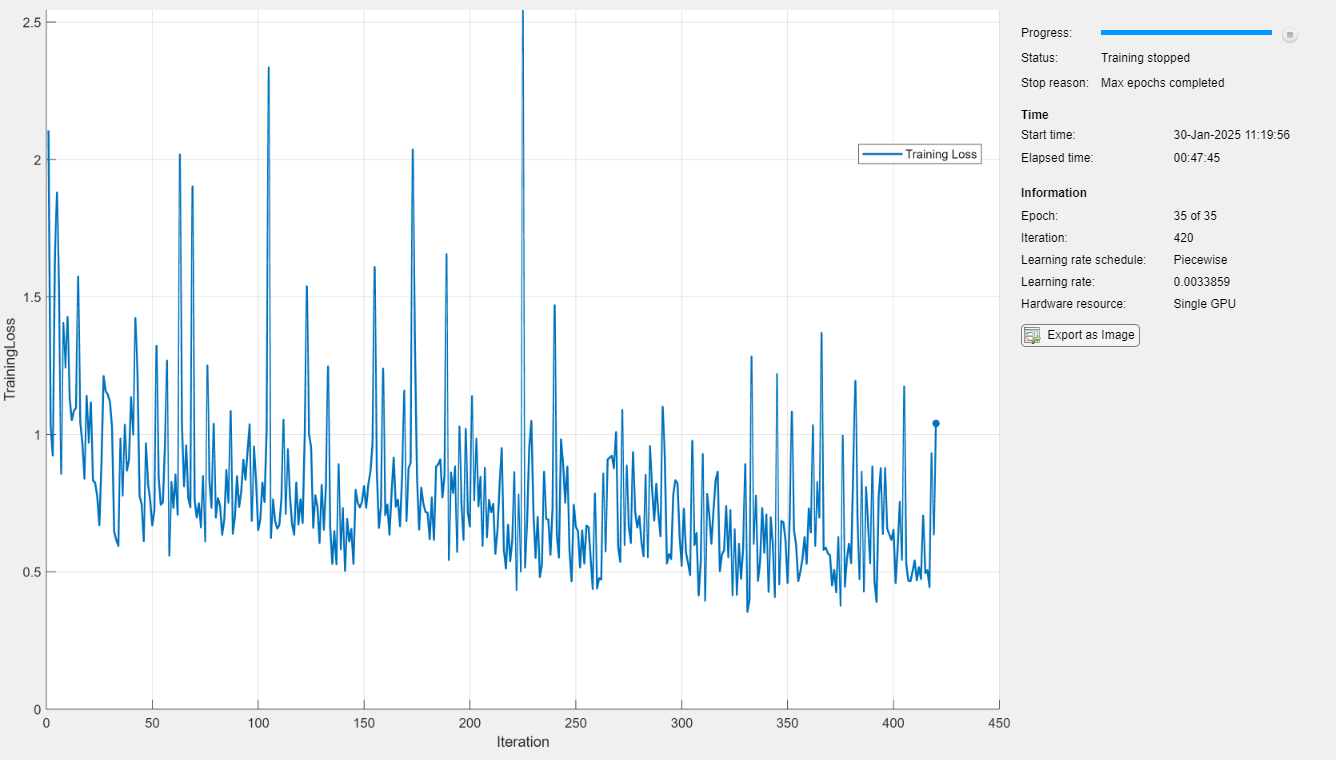

%Randlanet model training

% Train the network on the ldsTransformed datastore using 
% the trainnet function.
trainedNet = trainnet(preprocessedTrainingData,net,@(ypred,ytrue) helperLossFunction(ypred,ytrue,weights),options);

savePath = fullfile(modelFolder, 'trainedNet.mat'); % Saves trained model in the model folder
save(savePath, 'trainedNet');